## Task_ Session_2

% NAME:

These datasets were prepared using the power spectrum method, which computes the power of different frequency components. The task used to collect the data was a motor imagery paradigm, a common type of brain–computer interface (BCI). In each trial, the participant imagined a movement corresponding to the arrow shown on the screen. There were three possible classes—left hand, right hand, and foot—but in these datasets the subject performed only two of them.

Each dataset contains **100 rows and 10 columns**.

- **Rows** represent trials.

- **Columns 1–9** contain the power values for frequencies from **8 Hz to 16 Hz** (one column per frequency).

- **Column 10** is the class label, coded as either **0** or **1**.

You should do the following:

- **Remove the last column and compute the mean** of the remaining columns.

- **Define two functions** to compute outliers: one using the Standard Deviation rule and one using the IQR rule.

- **Calculate the Standard Deviation and IQR outliers** for all datasets using these functions.

- **Define a function** to visualize the data distribution using a histogram.

- **Apply the visualization function** to all datasets.

- **Create a box plot** for each dataset.

- **Discuss whether the visualizations are reliable.**

clear;
load('c3_PSD_trials_class1.mat'); 
c3_class1 = c3_PSD_trials_class1;
data = mean(c3_class1(:,1:end-1),2);

[outliers_sd_idx, lower_sd_bound, upper_sd_bound] = compute_outlier(data);

function [outliers_sd_idx, lower_sd_bound, upper_sd_bound] = compute_outlier(amplitudes_at_peak)
    data_mean = mean(amplitudes_at_peak);
    data_std = std(amplitudes_at_peak);
    data_q1 = prctile(amplitudes_at_peak, 25);
    data_q3 = prctile(amplitudes_at_peak, 75);
    data_iqr = data_q3 - data_q1;

Standard Deviation Rule (+/-3 SD from mean):
  Lower Bound: -1.27 uV, Upper Bound: 9.85 uV
  Number of outliers detected: 0


    
    % Method 1: Standard Deviation Rule (e.g., beyond \xB13 SD from the mean)
    % This method assumes a roughly normal distribution.
    std_threshold = 3; % Common threshold for SD rule
    lower_sd_bound = data_mean - std_threshold * data_std;
    upper_sd_bound = data_mean + std_threshold * data_std;
    
    outliers_sd_idx = (amplitudes_at_peak < lower_sd_bound) | (amplitudes_at_peak > upper_sd_bound);
    num_outliers_sd = sum(outliers_sd_idx);
    
    fprintf('Standard Deviation Rule (+/-%.0f SD from mean):\n', std_threshold); % Changed to +/-
    fprintf('  Lower Bound: %.2f uV, Upper Bound: %.2f uV\n', lower_sd_bound, upper_sd_bound);
    fprintf('  Number of outliers detected: %d\n', num_outliers_sd);
    if num_outliers_sd > 0
        fprintf('  Outlier amplitudes: %s uV\n', mat2str(amplitudes_at_peak(outliers_sd_idx)'));
    end
end









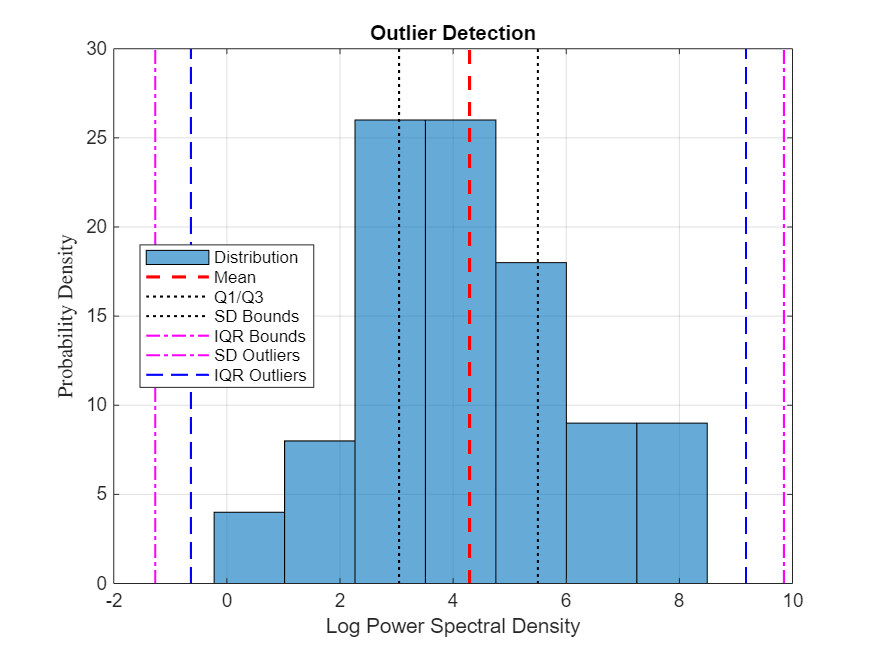

clear;
load('c3_PSD_trials_class1.mat'); 
c3_class1 = c3_PSD_trials_class1;
data = mean(c3_class1(:,1:end-1),2);


% Visual Inspection 1: Histogram

data_mean = mean(data);
data_std  = std(data);
q1 = prctile(data,25);
q3 = prctile(data,75);
iqr_val = q3 - q1;

% ---- Bounds ----
std_thresh = 3;
lower_sd_bound = data_mean - std_thresh*data_std;
upper_sd_bound = data_mean + std_thresh*data_std;

iqr_factor = 1.5;
lower_iqr_bound = q1 - iqr_factor*iqr_val;
upper_iqr_bound = q3 + iqr_factor*iqr_val;

% ---- Outliers ----
outliers_sd_idx  = (data < lower_sd_bound)  | (data > upper_sd_bound);
outliers_iqr_idx = (data < lower_iqr_bound) | (data > upper_iqr_bound);
iqr_only_idx = outliers_iqr_idx & ~outliers_sd_idx;

% ---- Plot ----
figure('Name','Outlier Visualization');

h = histogram(data,'Normalization','pdf', 'BinLimits',[min(data) max(data)]); hold on;

% Mean
plot([data_mean data_mean], ylim, 'r--', 'LineWidth',1.5);

% Q1/Q3
plot([q1 q1], ylim, 'k:', 'LineWidth',1);
plot([q3 q3], ylim, 'k:', 'LineWidth',1);

% SD bounds
plot([lower_sd_bound lower_sd_bound], ylim, 'm-.', 'LineWidth',1);
plot([upper_sd_bound upper_sd_bound], ylim, 'm-.', 'LineWidth',1);

% IQR bounds
plot([lower_iqr_bound lower_iqr_bound], ylim, 'b--', 'LineWidth',1);
plot([upper_iqr_bound upper_iqr_bound], ylim, 'b--', 'LineWidth',1);

% Outlier markers
scatter(data(outliers_sd_idx), zeros(sum(outliers_sd_idx),1), 100, 'm', 'filled');
scatter(data(iqr_only_idx),   zeros(sum(iqr_only_idx),1),   100, 'c', 'filled');

% Legend
legend({'Distribution','Mean','Q1/Q3','SD Bounds','IQR Bounds','SD Outliers','IQR Outliers'}, ...
        'Location','best');

% Labels
title('Outlier Detection');
xlabel('Log Power Spectral Density');
ylabel('Probability Density','Interpreter','latex');
grid on;